# Symbolic Math ToolBox

Provides functions for solving, plotting and manipulating symbolic maths equations

- Ordinary Differntial Equation

- Equation Simplification

- Calculus

- Equation Manipulation

- Linear Algebra

Results displayed in **Mathematical Typeset** : 

syms x
eq = sqrt(x+3/10) == 0

$$eq = \sqrt{x+\frac{3}{10}}=0$$

# Simple 2D Graphs

## Simple Graphs: Functions of a single real variable

**    Q. To plot **$\mathrm{sin}\left(\frac{10}{\left(1+x^2 \right)}\right)$

syms x
f = sin(10/(1+x^2));

$$f = \sin\left(\frac{10}{x^{2}+1}\right)$$

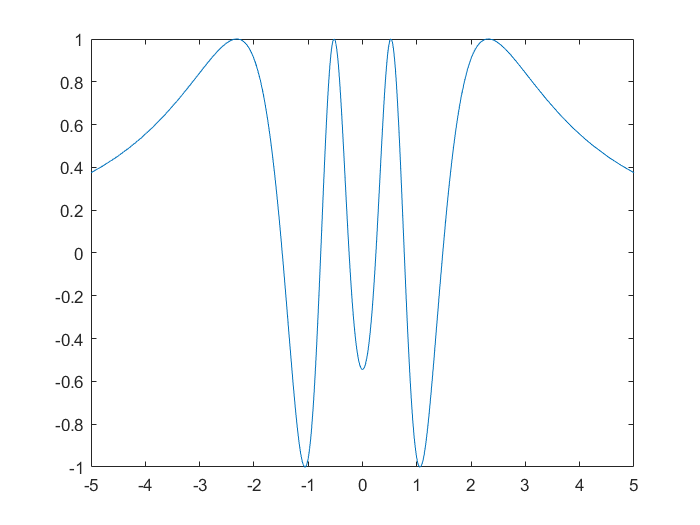

fplot(f)

**Default range of x is [-5,5]. To override:**

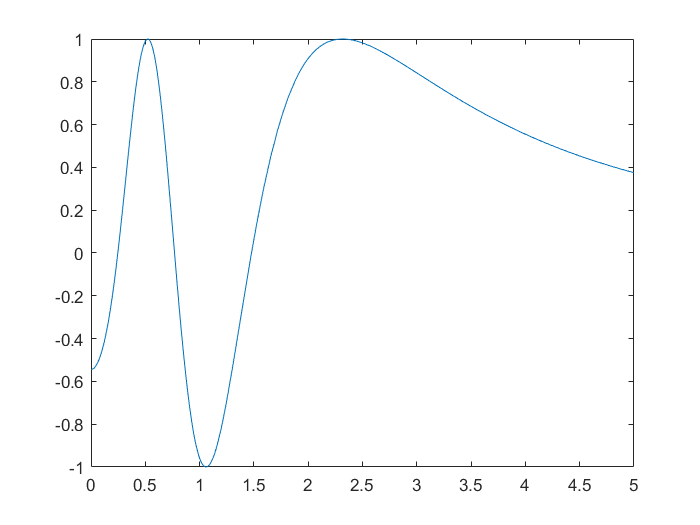

fplot(f,[0,5])

**Q. Draw graphs of many functions in the same plot.**

syms x
fplot( [sin(x) cos(x)], [-2*pi 2*pi])
legend show
title('sin(x) and cos(x) from -2*pi to 2*pi')
% To modify the properties of the graph

ax = gca

ax =   Axes (sin(x) and cos(x) from -2*pi to 2*pi) with properties:

             XLim: [-6.2832 6.2832]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


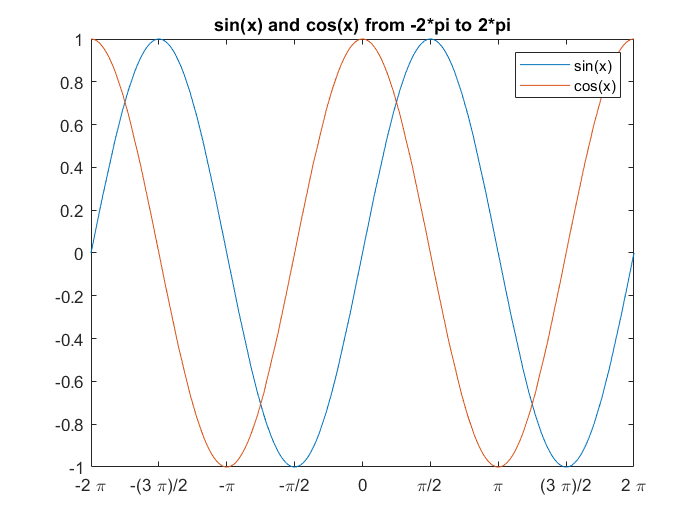

S = sym(ax.XLim(1):pi/2:ax.XLim(2));
ax.XTick = double(S);
ax.XTickLabel = arrayfun(@texlabel, S, 'UniformOutput', 0);

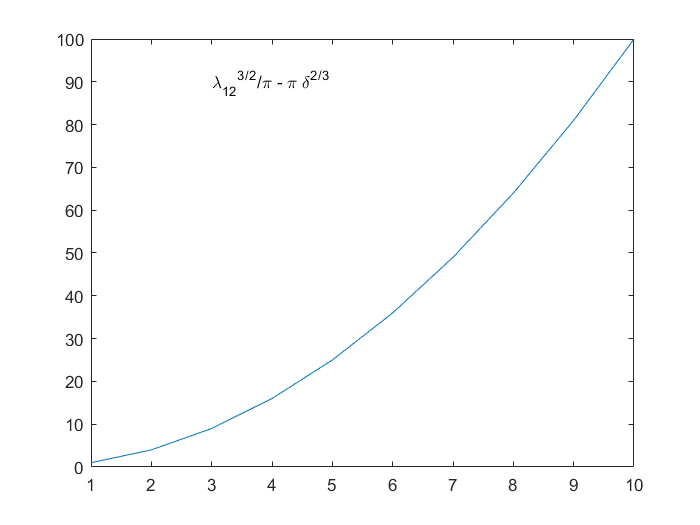

plot((1:10).^2)
txt = texlabel('lambda12^(3/2)/pi - pi*delta^(2/3)');
text(3,90,txt)

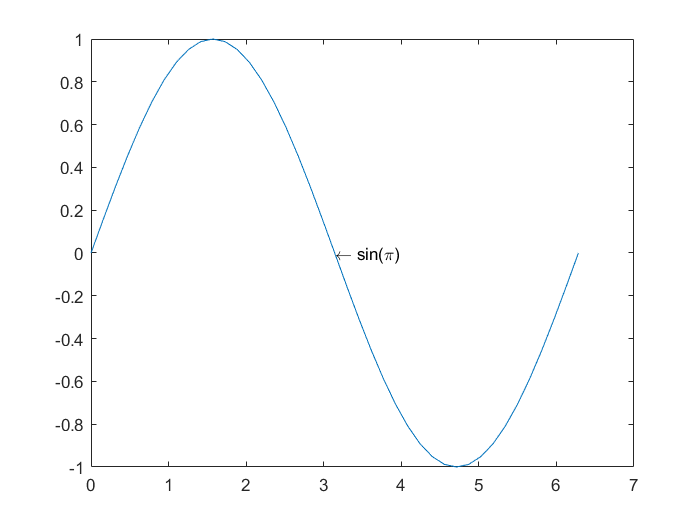

x = 0:pi/20:2*pi;
y = sin(x);
plot(x,y)
text(pi,0,'\leftarrow sin(\pi)')

# Parametric Plots

## **Q. Plot an ellipse given by **$\mathit{\mathbf{x}}=2\;\mathbf{cos}\left(\mathit{\mathbf{t}}\right)$ and $\mathit{\mathbf{y}}=\mathbf{sin}\left(\mathit{\mathbf{t}}\right)$**.**

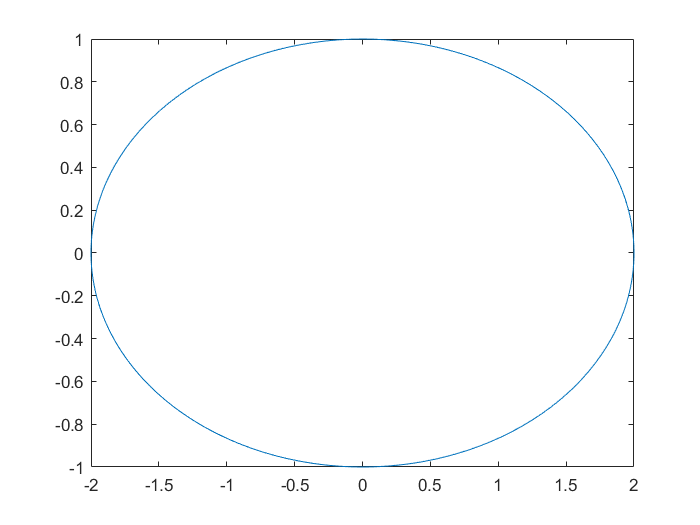

syms x y t
x = 2*cos(t);
y = sin(t);
fplot(x,y);

**Q. Plot a hyperbola.**

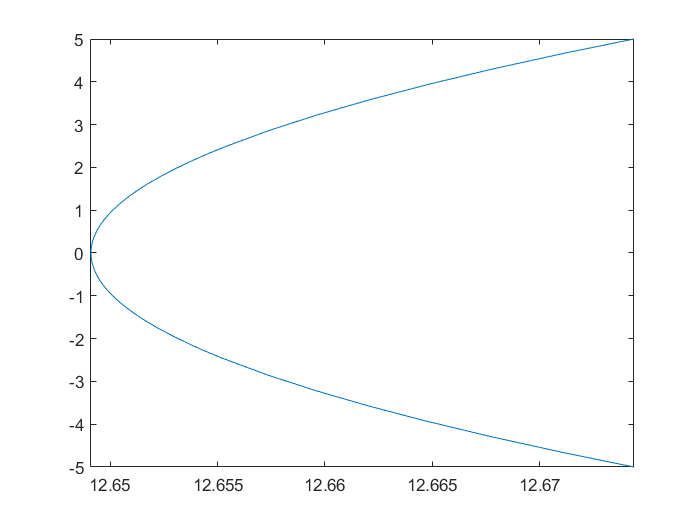

syms x y
x = t;
y = 4*sqrt(10+(t/25)^2);
fplot(y,x);

# Polar Plots

## Q. Plot a left-leafed horizontal cardioid.

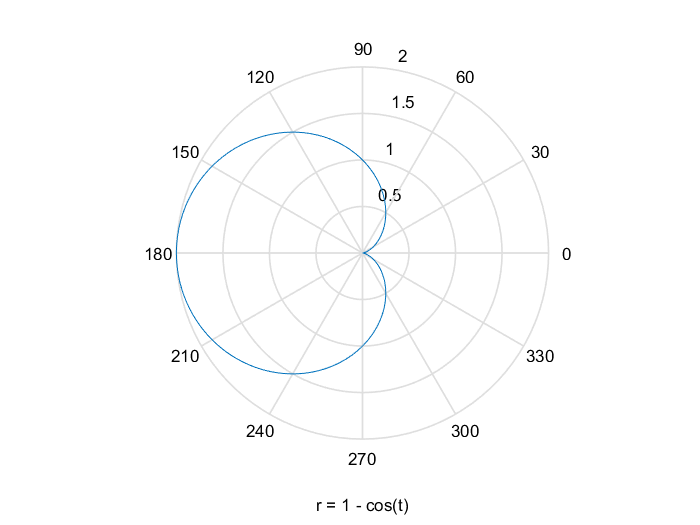

syms t
ezpolar(1-cos(t), [0 2*pi])

# 2D Visualization of Functions

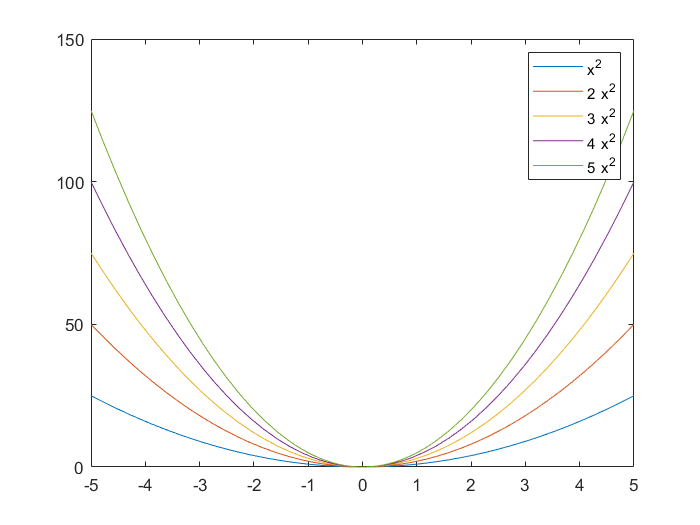

syms x
axis([-5 5 0 150])

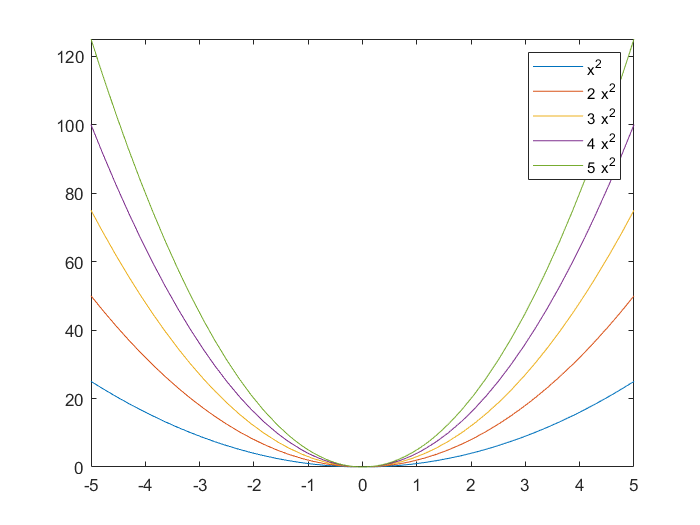

for a=1:5
    fplot(a*x^2)
    hold on
end
hold off
legend show

# 3D Visualization of Functions

## Q. Plot the function $a\left(x^2 +y^2 \right)$ using Symbolic Math Toolbox.

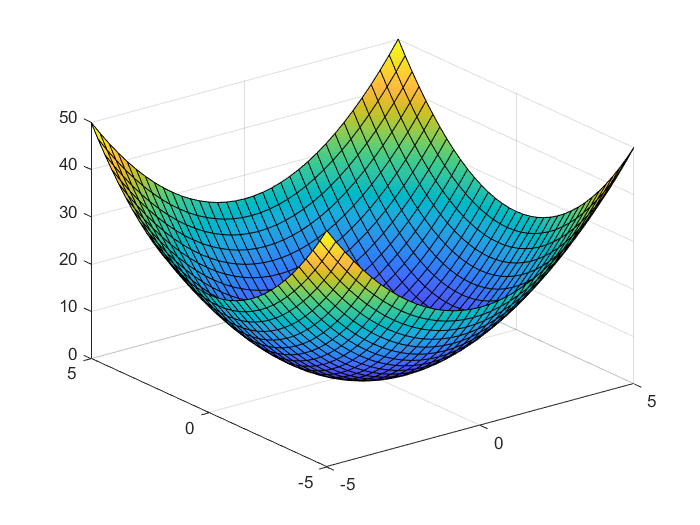

% Symblic functions cannot use surf()
% when a = 1
syms x y
f = x^2 + y^2;
fsurf(f)

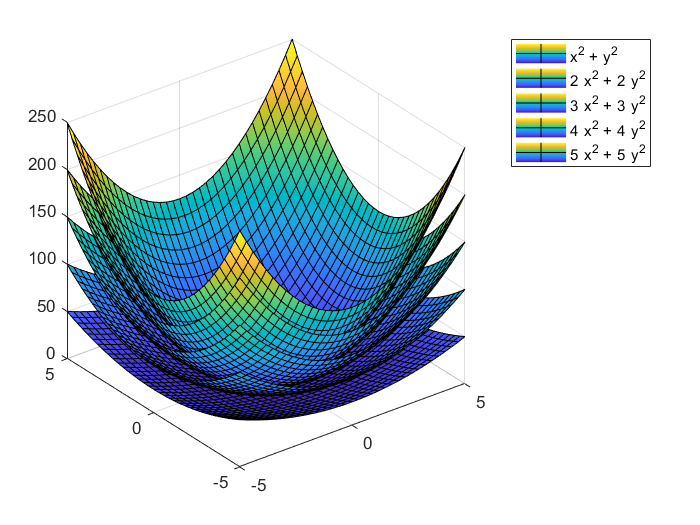

% For multiple values of a
for a = 1:5
    fsurf(a*(f))
    hold on
end
hold off
legend show

## Q. Plot both leaves of the lemniscate $r^2 =\mathrm{cos}\left(2\theta \right)$.

syms t
ezpolar(sqrt(cos(2*t)))

## Q. Obtain the plot of the "Somberero Function" (named, because of the visual similarity to  a hat).

                                                        $z=\frac{\mathrm{sin}\left(r\right)}{r}\mathrm{where}\;r=\sqrt{x^2 +y^2 }$ **between the range **$\left|x\right|\le 15\;\mathrm{and}\;\left|y\right|\le 15$

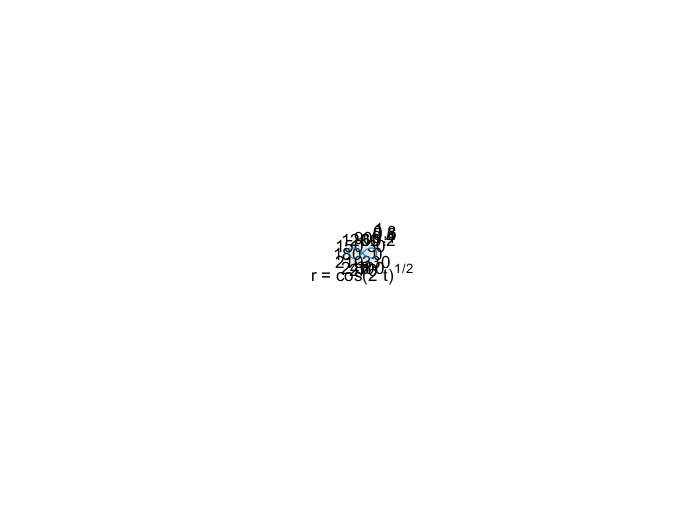

syms r x y
axis ([-15 15 -15 15])

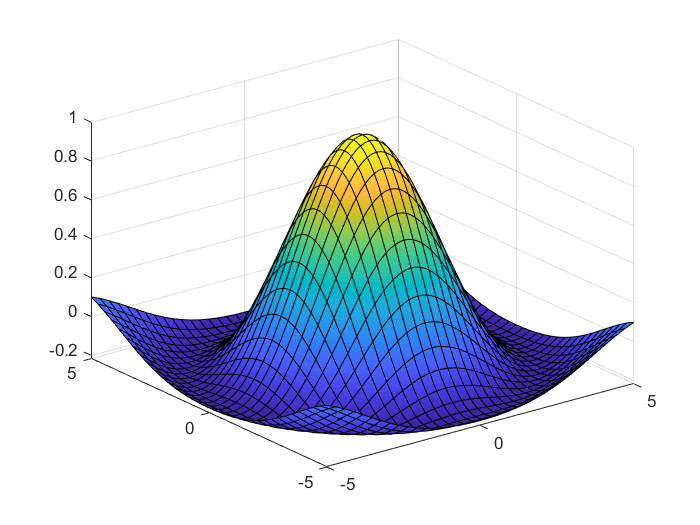

r = sqrt(x^2 + y^2);
z = sin(r)/r;
fsurf(z)

# Evaluating an expression at a given point

## Q. To evaluate the expression $x^2 +3x+2$ at $x=2$.

syms x
f(x) = x^2 + 3*x + 2;
f(3)

$$ans = 20$$

## Q. To evaluate $r=x^2 +y^2 +z^2$ at the point (x,y,z)=(1,2,3)

syms x y z
r(x,y,z) = x^2 + y^2 + z^2;
r(1,2,3)

## Q. Evaluate the expressions at the given value:

# Solving equations numerically

**To obtain all x satisying the equation:**$f\left(x\right)=g\left(x\right)$       

## Q. Solve the equation :$\mathrm{sin}\left(x\right)=x^3 -5x^2 +4$

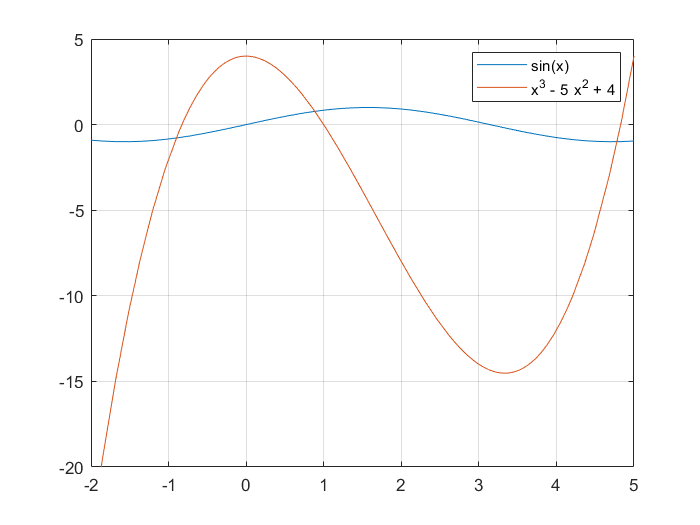

syms x
f1 = sin(x);
f2 = x^3-5*(x^2)+4;
fplot([f1 f2])
grid on

ylim([-20 5])
xlim([-2 5])
legend
%It solves the equation but does not plot them.
%Use text command to include the points on the graph.
sol1 = vpasolve(f1==f2, x, -1);

Error using text
Non-numeric data is not supported in 'Text'

sol2 = vpasolve(f1==f2, x, 1);
sol3 = vpasolve(f1==f2, x, 4);
text(x,f1,'text')

## Q. Solve the equations:

            
$$\begin{array}{l}
x^2 -x-2025=0\\
x^3 -6x^2 -20x^2 +113x+60=0\\
2x^4 -1{\mathrm{1x}}^3 -20x^2 +113x+60=0
\end{array}$$


## Q. Find real solutions of equation $\mathrm{xsin}\left(x\right)=\frac{1}{2}$ for x in following range

           
$$\begin{array}{l}
0<x<2\\
2<x<4\\
6<x<7\\
8<x<10\\
\mathrm{Verify}\;\mathrm{graphically}\;\mathrm{that}\;\mathrm{there}\;\mathrm{are}\;\mathrm{no}\;\mathrm{solutions}\;\mathrm{in}\;\mathrm{range}\;4<x<6
\end{array}$$


##  Q. Use 'plot' to find the number and approx. number of real soltutions of $x^3 +3x^2 +2x+1=0$.

## OBTAINING ONLY REAL SOLUTIONS TO AN EQUATION:

syms x
% Solving the equation under all assumption
solve(x^4==1,x)

$$ans = 1$$

assume(x,'real')
assumeAlso(x>0)
%Listing all the assumptions of x
assumptions(x)

$$ans = \left(\begin{array}{cc} x\in \mathbb{R} & 0<x \end{array}\right)$$

solve(x^4==1,x)

$$ans = 1$$